## gain scheduled blade pitch control

load("SS_IEA15MW.mat")
load("linear_IEA15MW.mat");
load("aeroloads_IEA15MW.mat");
load('componentsIEA15MW.mat');
load("bladedata_IEA_15MW.mat");
load("ROSCO_IEA15MW.mat");


$$\textrm{KP}=2\frac{J}{\textrm{kt}}\;\omega_n \;\xi +\frac{k_{\omega \;} }{\textrm{kt}};\textrm{KP}\approx \frac{\left(2J\omega_n \;\xi \omega_0 \right)}{\frac{\textrm{dP}}{d\theta \;}}$$



$$\textrm{KI}=\frac{J}{\textrm{kt}}\;\omega_n^2 \;;\textrm{KI}=\frac{\left(J\omega_n^2 \;\omega_0 \right)}{\frac{\textrm{dP}}{d\theta \;}}$$


parameters

wn=0.03; % frequency (rad/s)
csi=0.1; % damping ratio (-)

J=WTcomponents.rotorInertia; % rotor inertia
w0=SS.ROTSPD(end)*pi/30; % rated rotor speed
KP=J.*(2*wn*csi*w0)/10^6; % (rad/s)/deg
KI=J*wn^2/10^6; % rad/deg

ROSCO.theta=linear.theta;
ROSCO.KP=KP./linear.pitchSensitivity_approx;
ROSCO.KI=KI./linear.pitchSensitivity_approx;

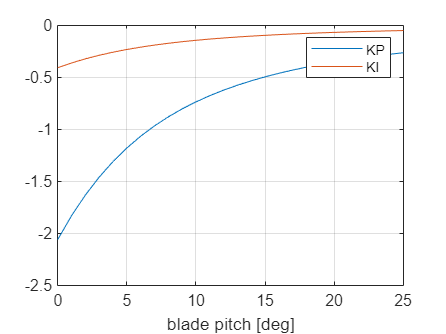

clf
plot(ROSCO.theta,ROSCO.KP,ROSCO.theta,ROSCO.KI)
hold on
xlabel("blade pitch [deg]")
legend("KP","KI")
grid on

## Feedback speed gain


$$\theta =\textrm{KP}\;\omega +\textrm{KI}\;\int \omega \;\textrm{dt}+\textrm{KV}\;v_{\textrm{nacelle}}$$


to reduce negative damping of rotor for floating condition, a further parameter KV is added

ROSCO.KV = 9.75;

## tip speed ratio (TSR) tracking control

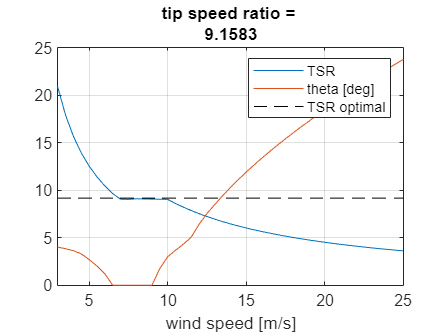

clf
i=find(SS.BLADEPITCH<=0.2);
TSR_vec=SS.ROTSPD*pi/30*bladedata.radius(end)*cosd(3+5)./SS.WINDSPEED;
TSR_opt=mean(TSR_vec(i));
plot(SS.WINDSPEED,TSR_vec,SS.WINDSPEED,SS.BLADEPITCH,[3 25],[1 1]*TSR_opt,'--k')
title(["tip speed ratio = " num2str(TSR_opt)])
legend("TSR","theta [deg]","TSR optimal")
xlabel("wind speed [m/s]")
xlim([3 25])
grid on

ROSCO.TSR_opt=TSR_opt;
ROSCO.Rtip=bladedata.radius(end)*cosd(WTcomponents.hub.precone+WTcomponents.nacelle.tiltangle);

## generator torque control

parameters:

wn=0.12; % frequency (rad/s)
csi=2; % damping ratio (-)
ROSCO.thetaRate=deg2rad(7); % max blade pitch rate
ROSCO.torqueMaxRate=4500000; %max generator torque rate

ROSCO.KP_tau = -2*J*wn/csi*0.6; % [Nm/(rad/s)]
ROSCO.KI_tau = -J*wn^2*0.6; % [Nm/(rad)]
ROSCO.omegaMax = SS.ROTSPD(end);
ROSCO.omegaMin = SS.ROTSPD(1);
ROSCO.torqueMax = (SS.POWER(end)/(SS.ROTSPD(end)*pi/30/10^6))*1.065;

## set point smoothing

ROSCO.SPS_Kb=1;
ROSCO.SPS_kt=0.001;
ROSCO.WS=SS.WINDSPEED;

## wind speed and rotor speed filters

[ROSCO.windFilter.A,ROSCO.windFilter.B,ROSCO.windFilter.C,ROSCO.windFilter.D] = tf2ss(1,[4 4 1]);
[ROSCO.omegaFilter.A,ROSCO.omegaFilter.B,ROSCO.omegaFilter.C,ROSCO.omegaFilter.D] = tf2ss(1,[0.2 1 1]);
ROSCO.pitchfilter.A=6;
ROSCO.pitchfilter.B=10;
ROSCO.SPSfilter.A = 1.6;

## save data

save("ROSCO_IEA15MW","ROSCO")